# Representación Funcional de una Señal

### Función 1

x(n)={1, para n=1,3; 4, para n=2; 0, en otro caso}

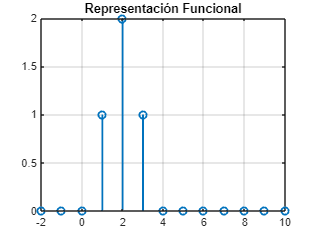

n = -2:10;
x_n = zeros(size(n));
for i=1:length(n)
    x_n(i) = x(n(i));
end

stem(n, x_n, 'Marker', 'o', 'LineWidth', 1.5);
title('Representación Funcional');
grid on;     

### Función 2

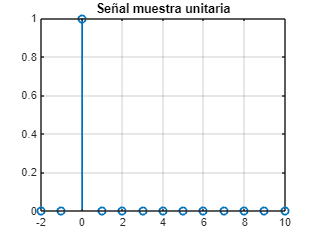

delta_n = zeros(size(n));
for i=1:length(n)
    delta_n(i) = delta(n(i));
end

stem(n, delta_n, 'Marker', 'o', 'LineWidth', 1.5);
title('Señal muestra unitaria');
grid on;

### Función 3

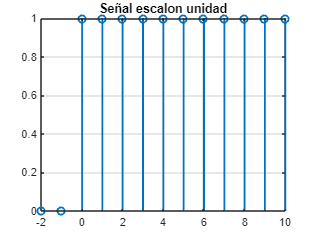

escalon_n = zeros(size(n));
for i=1:length(n)
    escalon_n(i) = escalon(n(i));
end

stem(n, escalon_n, 'Marker', 'o', 'LineWidth', 1.5);
title('Señal escalon unidad');
grid on;

### Función 4

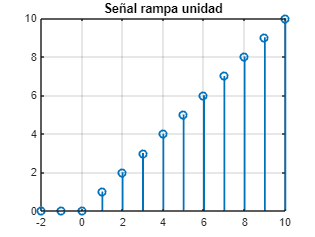

rampa_n = zeros(size(n));
for i=1:length(n)
    rampa_n(i) = rampa(n(i));
end

stem(n, rampa_n, 'Marker', 'o', 'LineWidth', 1.5);
title('Señal rampa unidad');
grid on;

### Función 5

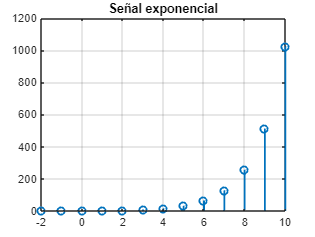

exponencial_n = zeros(size(n));
a = 2  ;
for i=1:length(n)
    exponencial_n(i) = exponencial(n(i),a);
end

stem(n, exponencial_n, 'Marker', 'o', 'LineWidth', 1.5);
title('Señal exponencial');
grid on;

### Función 1

function res = x(n)
    if n==1 || n==3
        res = 1;
    elseif n==2
        res=2;
    else
        res=0;
    end
end

### Función 2

Señal muestra unitaria.

function res = delta(n)
    if n == 0
        res=1;
    else
        res=0;
    end
end

### Función 3

Señal escalón unidad  .

function res = escalon(n)
    if n >= 0
        res=1;
    else
        res=0;
    end
end

### Función 4

Señal rampa unidad  .

function res = rampa(n)
    if n >= 0
        res = n;
    else
        res = 0;
    end
end

### Función 5

Señal exponencial

function res = exponencial(n, a)
    res = a^n;
end